*In Thy Name*

# 
$$Biophysical \: simulation \: of \: predictive \: three \: cues \: task$$


*Implemented on *$MatLab$* - *$DynaSim(dS)/DynaLearn(dL)$

#### *Task and model are based on : *$Layer \: and \: rhythm \: specificity \: for \: predictive \: routing - \: A.M \: Bastos \: et. \: al - \: 2020$

#### *Requirement: *$DynaSim/dev$* latest version on *$R2019a$* or later versions of *$MatLab$


$$Created \: on \: : \: 1st
 \: of \: July, \: 2022$$



$$Github:@DynaSim, @HNXJ$$


## $I.$* Model parameters*

Function "dlModelPredictivePFC" is implemented on dL.dS in order to generate 3-layer laminar cortex model of *Bastos2020. *It takes *Ne *(size of the populations in excitatory layer), *Ni *(size of the populations in inhibitory layers), *Nin *(size of inputs/stimuli populations) and *NoiseRate *(max amplitude of the uniform noise in the presynaptic potentials).

Layer (population) sizes are custom but we've chosen numbers similar to the biological details of the PFC. It is recommended to choose multiples of 6 as population sizes as our task has 3 cues passed as 6 stimuli; 3 before delay and 3 after the delay in the middle of task.

Noise rate of 5 means that a random process with max voltage amplitude of 5 will be added to the presynaptic potentials; this value is believed to be close to the noisy processes in the most neural circuits [source to be included later, values may change]

clear;clc;
Ne = 24;Ni = 6;Nin = 6;NoiseRate = 5;
s = dlModelPredictivePFC(Ne, Ni, Nin, NoiseRate); % Predictive PFC model with specific parameters


->Initialization of dlPFC Laminar Model: 
-->Excitatory layer neuronal population size = 24 (recommended to be multiple of 6), 
-->Inhibitory layer neuronal population size = 6 (recommended to be multiple of 6 and at least 3 times smaller than Excitatory size), 
-->Input layer (terminal) neuronal population size = 6 (arbitrary, better to be close to Inhibitory layer size), 
-->Overall noise rate = 5.0000, 
--->Connecting separate layers and inputs:
->Initialization of dlPFC done. 


### *Create DynaLearn Class (Only first time, if model file does not exist already)*

After creating dS model, it's time to construct dL object based on it in a specific directory.

Generally it should be something like this; You can change the path to the *studydir *in *DynaLearn(dsStruct, ''path/to/studydir');.*

As we aim to run model on hundred to thousand of trials, we've implemented DynaLearn on *coder/mexgen *of Matlab too; it takes several minutes to generate mex interface so try to save the model after running this. Consider using previously saved model later.

m = DynaLearn(s, 'models/dlModelPredictivePFC2'); % ~ 90 min, MEXGEN
m.dlSave(); % < 1sec


->Model saved in "models/dlModelPredictivePFC2/dlFile.mat".


### *Load DynaLearn Class*

If you have the previously saved/constructed model, load it like this:

m = DynaLearn(); % ~ 1sec, create empty object



@DS.DL:Creating Dyna model object ... DL object loaded from models/dlBaseModel 
Params.mat file loaded from models/dlBaseModel 
--->Constructing graph ... Done.

Reinitialized.
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


m = m.dlLoad('models/dlModelPredictivePFC2'); % ~ 5sec, load from path

DL object loaded from models/dlModelPredictivePFC2 
Params.mat file loaded from models/dlModelPredictivePFC2 
--->Constructing graph ... Done.

Reinitialized.


m.dlSimulate(); % ~ 10sec, to test if its valid 

## $II.$*Load trial parameters*

Now we should load parameters required for trials. As the aim of this simulation is to repeat the trial-and-error task in the article, we should have correspounding stimulus-target pairs to calculate model error, accuracy and reaction times. The function *dlDemoThreePattern() *gives the trial parameters of the predictive coding task.

In the target parameters, two sterategies have been included; Decision of the model is based on winner-takes-all criterion so in the each case 

[trialParams1, trialParams2, trialParams3] = dlDemoThreePattern();

outputParams = [{'DeepE_V', 1:4, [300 500], 'afr'}; {'DeepE_V', 5:8, [300 500], 'afr'}; {'DeepE_V', 9:12, [300 500], 'afr'}];
targetParams1 = [{'MSE', 1, 18, 0.2}; {'MSE', 2, 12, 0.2}; {'MSE', 3, 12, 0.2}; {'Compare', [1, 2], 0, 0.3}; {'Compare', [1, 3], 0, 0.3}; {'Diff', [2, 3], 0, 0.04}]; % A 
targetParams2 = [{'MSE', 2, 18, 0.2}; {'MSE', 1, 12, 0.2}; {'MSE', 3, 12, 0.2}; {'Compare', [2, 1], 0, 0.3}; {'Compare', [2, 3], 0, 0.3}; {'Diff', [1, 3], 0, 0.04}]; % B
targetParams3 = [{'MSE', 3, 18, 0.2}; {'MSE', 2, 12, 0.2}; {'MSE', 1, 12, 0.2}; {'Compare', [3, 1], 0, 0.3}; {'Compare', [3, 2], 0, 0.3}; {'Diff', [1, 2], 0, 0.04}]; % C

## $III.$*Training session parameters*

Training session requires numereous parameters like learning method and its details. For a basic trial-and-error we use our novel "enhanced stochastic delta rule", which uses the logic behind delta rule except changes are stochastic and we save optimal states so if the model diverges much more than a certain ratio, the model continues again from previous checkpoint.

The function *dlTrialBlockGenerator(dlInputParameters, dlTargetParameters, BlockSize, TrialSize); *is also implemented to make input-target pairs required for the task.

dlInputParameters = {trialParams1, trialParams2, trialParams3};
dlTargetParameters = {targetParams1, targetParams2, targetParams3};
dlOutputParameters = outputParams;

TBdata = dlTrialBlockGenerator(dlInputParameters, dlTargetParameters, 50, 50);

dlTrainOptions = containers.Map();
dlTrainOptions('dlEpochs') = 1;
dlTrainOptions('dlBatchs') = 50;
dlTrainOptions('dlLambda') = 1e-5;
    
dlTrainOptions('dlCheckpoint') = 'true';
dlTrainOptions('dlCheckpointCoefficient') = 2.74; % A.K.A exploration rate 
dlTrainOptions('dlUpdateMode') = 'trial';
dlTrainOptions('dlLearningRule') = 'BioDeltaRule'; % Delta rule with a basic change based on biophysical properties 

dlTrainOptions('dlSimulationFlag') = 1;
dlTrainOptions('dlOutputLogFlag') = 1;
dlTrainOptions('dlOfflineOutputGenerator') = 0;
dlTrainOptions('dlAdaptiveLambda') = 0; % Adaptive lambda parameter; recommended for long simulations.

dlTrainOptions('dlLambdaCap') = 3e-2; % Only if Adaptive lambda is active, recommended to set a upper-bound (UB) or ignore to use default UB (0.01).

## $IV.$* Initial training on the model to reach a plausible local minimia *

Like the task in the paper the model should also learn the basics of the task. We shortly train the model by cues to put it close to a local minimia.

For shorter logs, we've only printed last 9 of 300 iterations (3 of 100 epochs) in here:

dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlEpochs') = 3; % 100 ...
dlTrainOptions('dlBatchs') = 3;
m.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

->Outputs log will be saved.
	Epoch no. 1 (Total iterations for this model : 291)
		Batch no. 1	Updating parameters of models/dlModelPredictivePFC2/solve	Updated.		Error = 19.893224
		Batch no. 2	Updating parameters of models/dlModelPredictivePFC2/solve	Updated.		Error = 5.286449
		Batch no. 3	Updating parameters of models/dlModelPredictivePFC2/solve	Updated.		Error = 8.337260
		Epoch's Average Error = 11.172311, Last lambda = 0.000020
	Epoch no. 2 (Total iterations for this model : 294)
		Batch no. 1	Updating parameters of models/dlModelPredictivePFC2/solve	Updated.		Error = 47.088121
		Batch no. 2	Updating parameters of models/dlModelPredictivePFC2/solve	Updated.		Error = 5.286160
		Batch no. 3	Updating parameters of models/dlModelPredictivePFC2/solve	Updated.		Error = 40.668709
		Epoch's Average Error = 31.014330, Last lambda = 0.000020
Checkpoint file loaded from models/dlModelPredictivePFC2/Optimal 
	Epoch no. 3 (Total iterations for this model : 297)
		Batch no. 1	Updating parame

### *Error log of initial training*

In the pretraining, you can see that although the model has explored with some degree of freedom in the longterm batch error has been reduced.

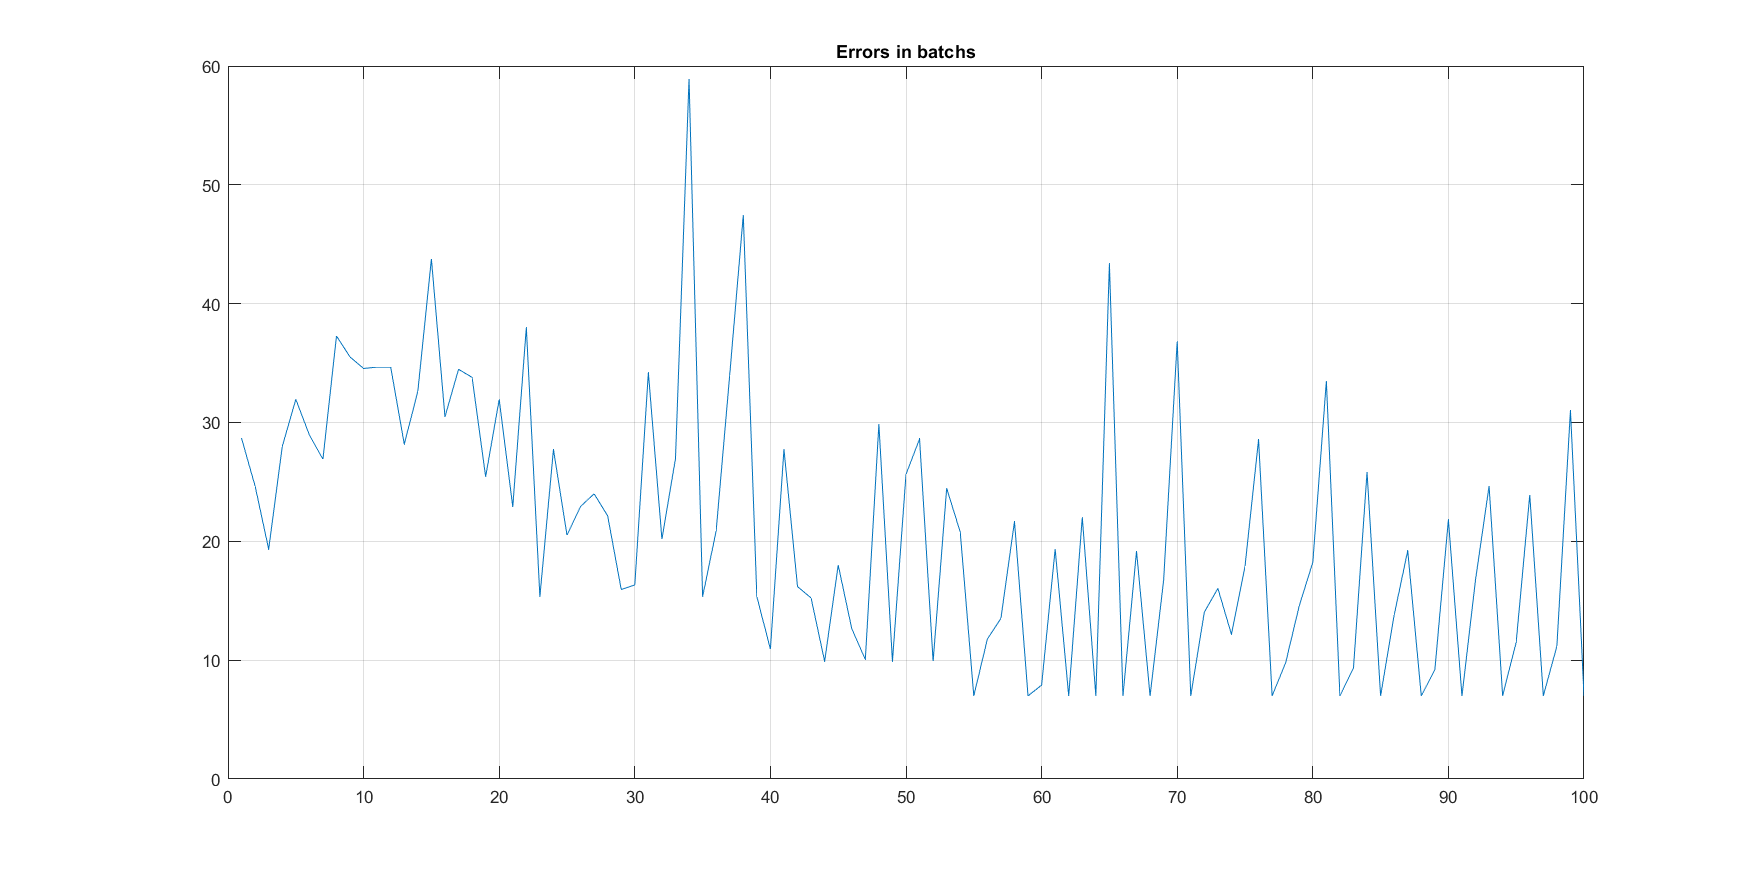

m.dlPlotBatchErrors(3);

## $V.$ *Block-trial phase*

Now our model is basically pre-trained to be on a local minimia; we can start the main session same as the real experiment. We change exploration rate and optimal error in every batch in order to prevent biases toward blocks in the start of each phase.

*To reduce log size, this cell's output has been cleared*

dlTrainOptions('dlUpdateMode') = 'trial';
dlTrainOptions('dlEpochs') = 1;
dlTrainOptions('dlBatchs') = 50;
dlTrainOptions('dlCheckpointCoefficient') = 4;
m.dlTrain(TBdata.B1, dlOutputParameters, TBdata.T1, dlTrainOptions);
dlTrainOptions('dlCheckpointCoefficient') = 7;
m.dlTrain(TBdata.TrB, dlOutputParameters, TBdata.TrT, dlTrainOptions);
dlTrainOptions('dlCheckpointCoefficient') = 4; 
m.dlTrain(TBdata.B2, dlOutputParameters, TBdata.T2, dlTrainOptions);
dlTrainOptions('dlCheckpointCoefficient') = 7; 
m.dlTrain(TBdata.TrB, dlOutputParameters, TBdata.TrT, dlTrainOptions);
dlTrainOptions('dlCheckpointCoefficient') = 4;
m.dlTrain(TBdata.B3, dlOutputParameters, TBdata.T3, dlTrainOptions);
dlTrainOptions('dlCheckpointCoefficient') = 7;
m.dlTrain(TBdata.TrB, dlOutputParameters, TBdata.TrT, dlTrainOptions);

## $VI.$ *Errors log plot*

Absolute error in trials; consider that this is not binary same as accuracy, we should calculate ...

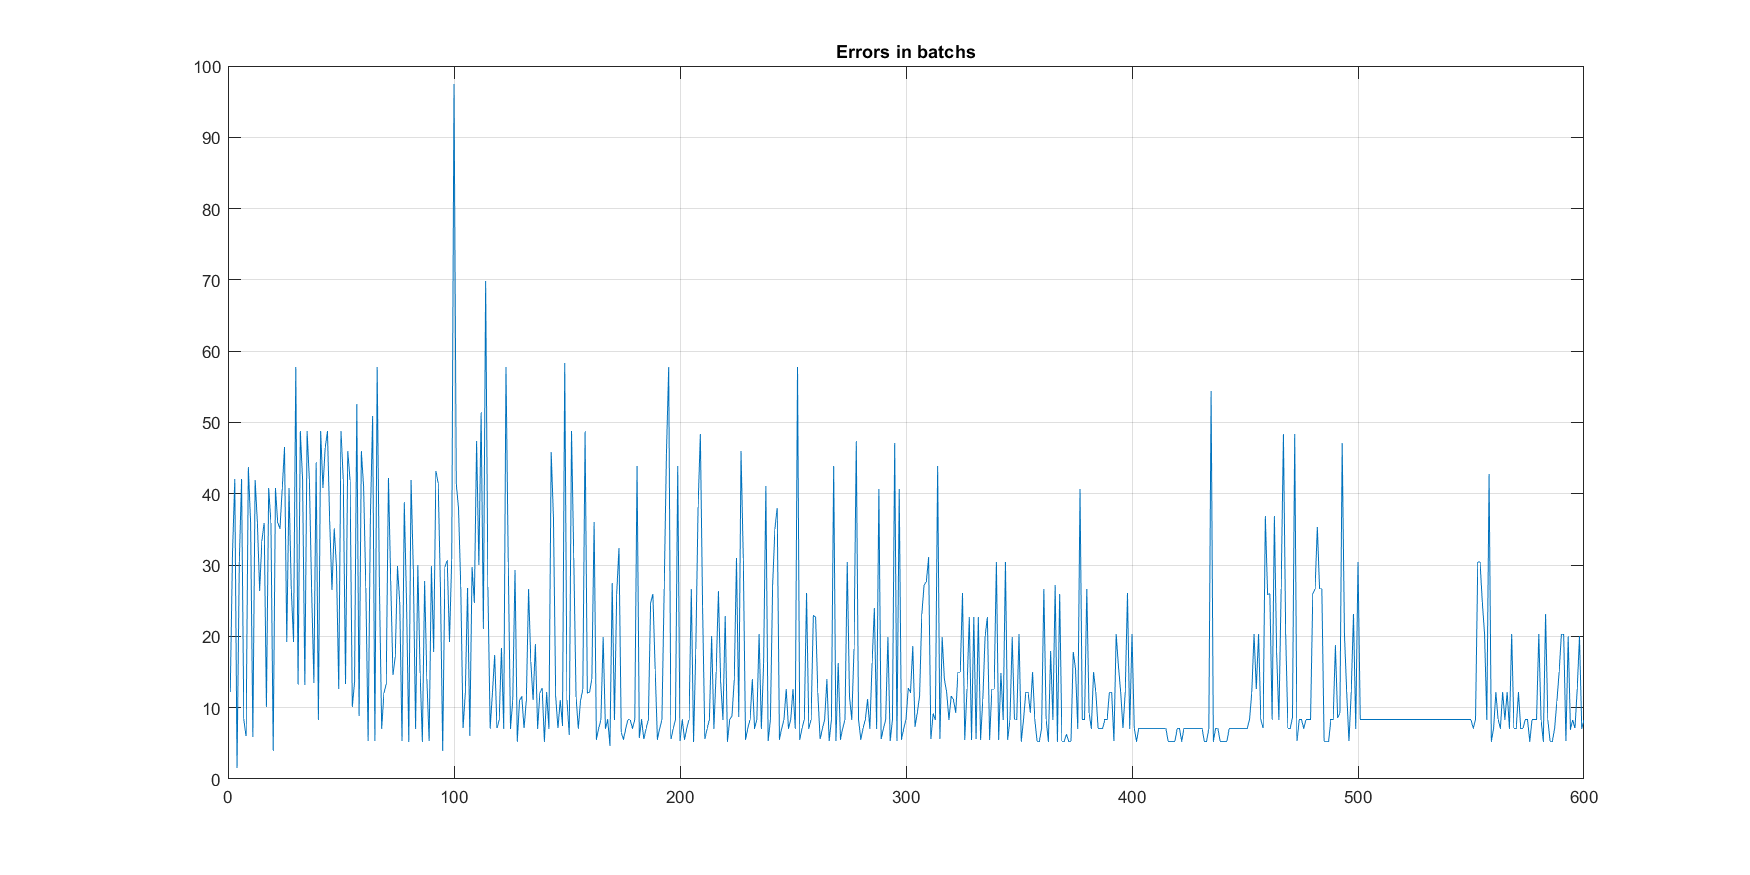

m.dlPlotBatchErrors(1);

## *Appendix*

## $A1.$ *Plot Local-field potentials (LFP)*

In this section, we are checking some electrophysiological properties of the simulation. Electrophysiological recording properties and outputs of simulation are also similar as the implemented model is based on laminar PFC. 

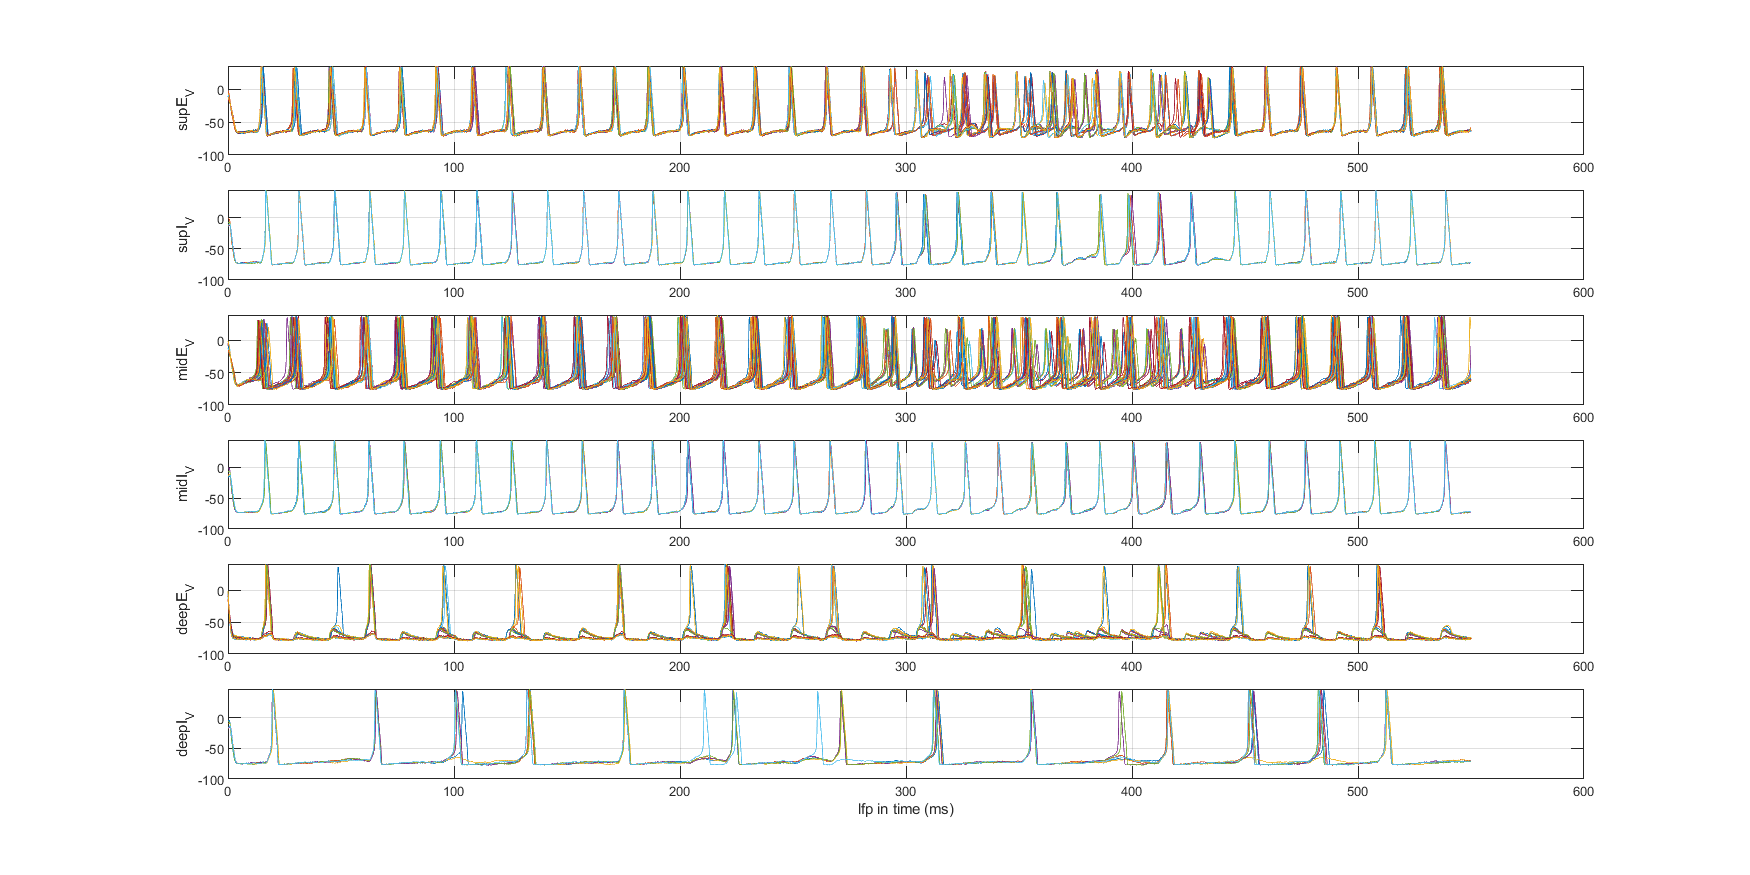

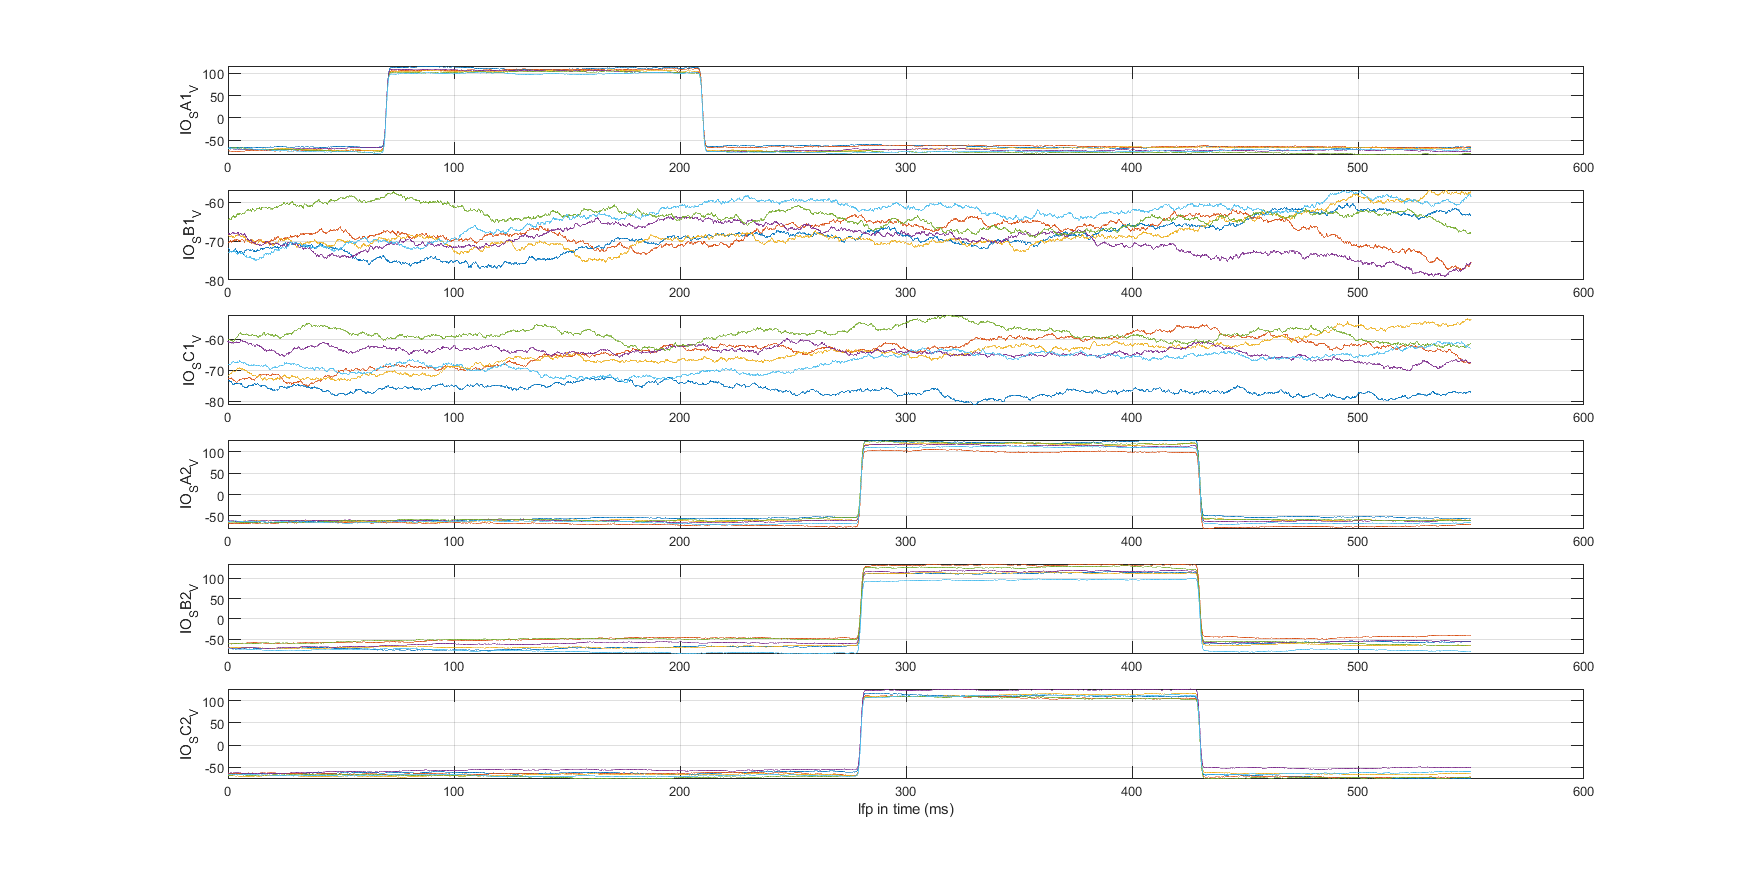

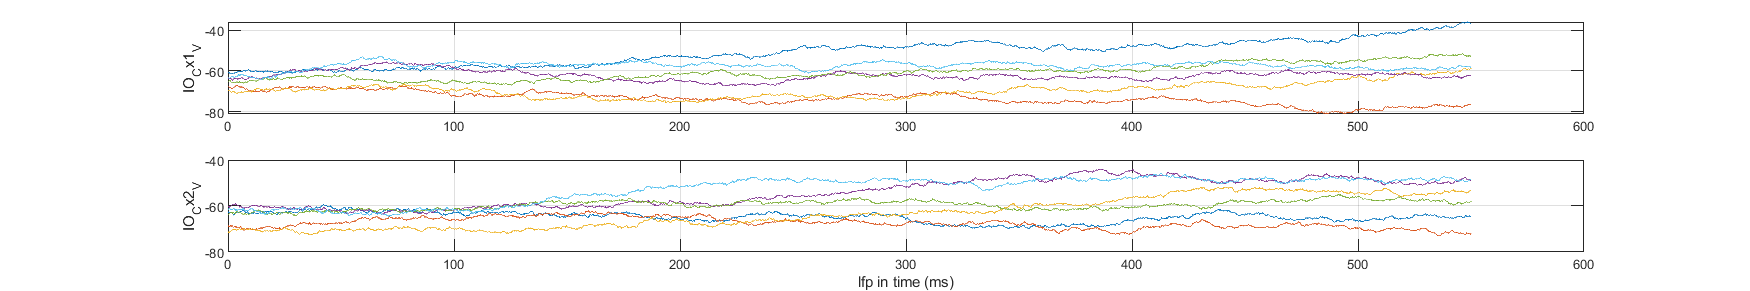

m.dlPlotAllPotentials('lfp');

## $A2.$*Run a trial on simulation without training*

This cell contains the example of simulation without training, in order to check outputs of the model [noise is also present at all stages]

Average firing rate in each output is printed:

for i = 1:3
    m.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
end


	Single trial running: 
Updating parameters of models/dlModelPredictivePFC2/solve	Updated.	
	Simulation outputs:     [15.0672]    [16.4549]    [15.1283]


	Single trial running: 
Updating parameters of models/dlModelPredictivePFC2/solve	Updated.	
	Simulation outputs:     [15.1778]    [21.9655]    [15.1030]


	Single trial running: 
Updating parameters of models/dlModelPredictivePFC2/solve	Updated.	
	Simulation outputs:     [11.0384]    [21.9662]    [16.4835]



## $A3.$* Spectral plots on different bands*

### *Gamma/Beta ratio*

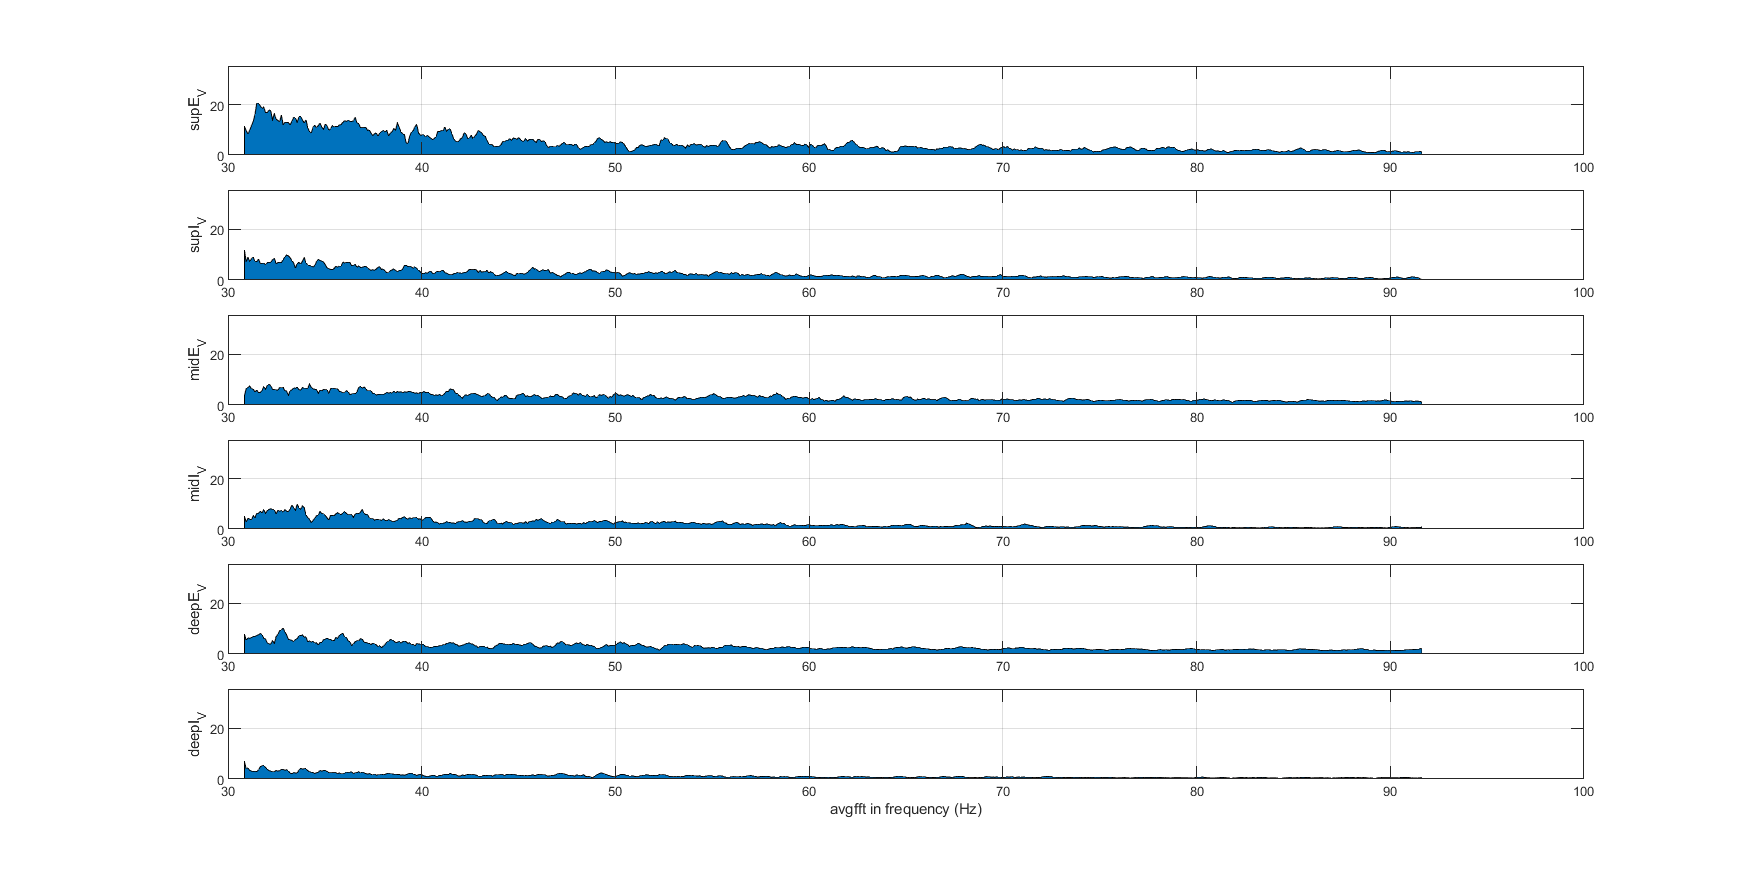

Temp edit for 6 subplots; average fft


opts = containers.Map();
opts("lf") = 33;
opts("hf") = 100;
m.dlPlotAllPotentials('avgfft', opts);

### *Beta*

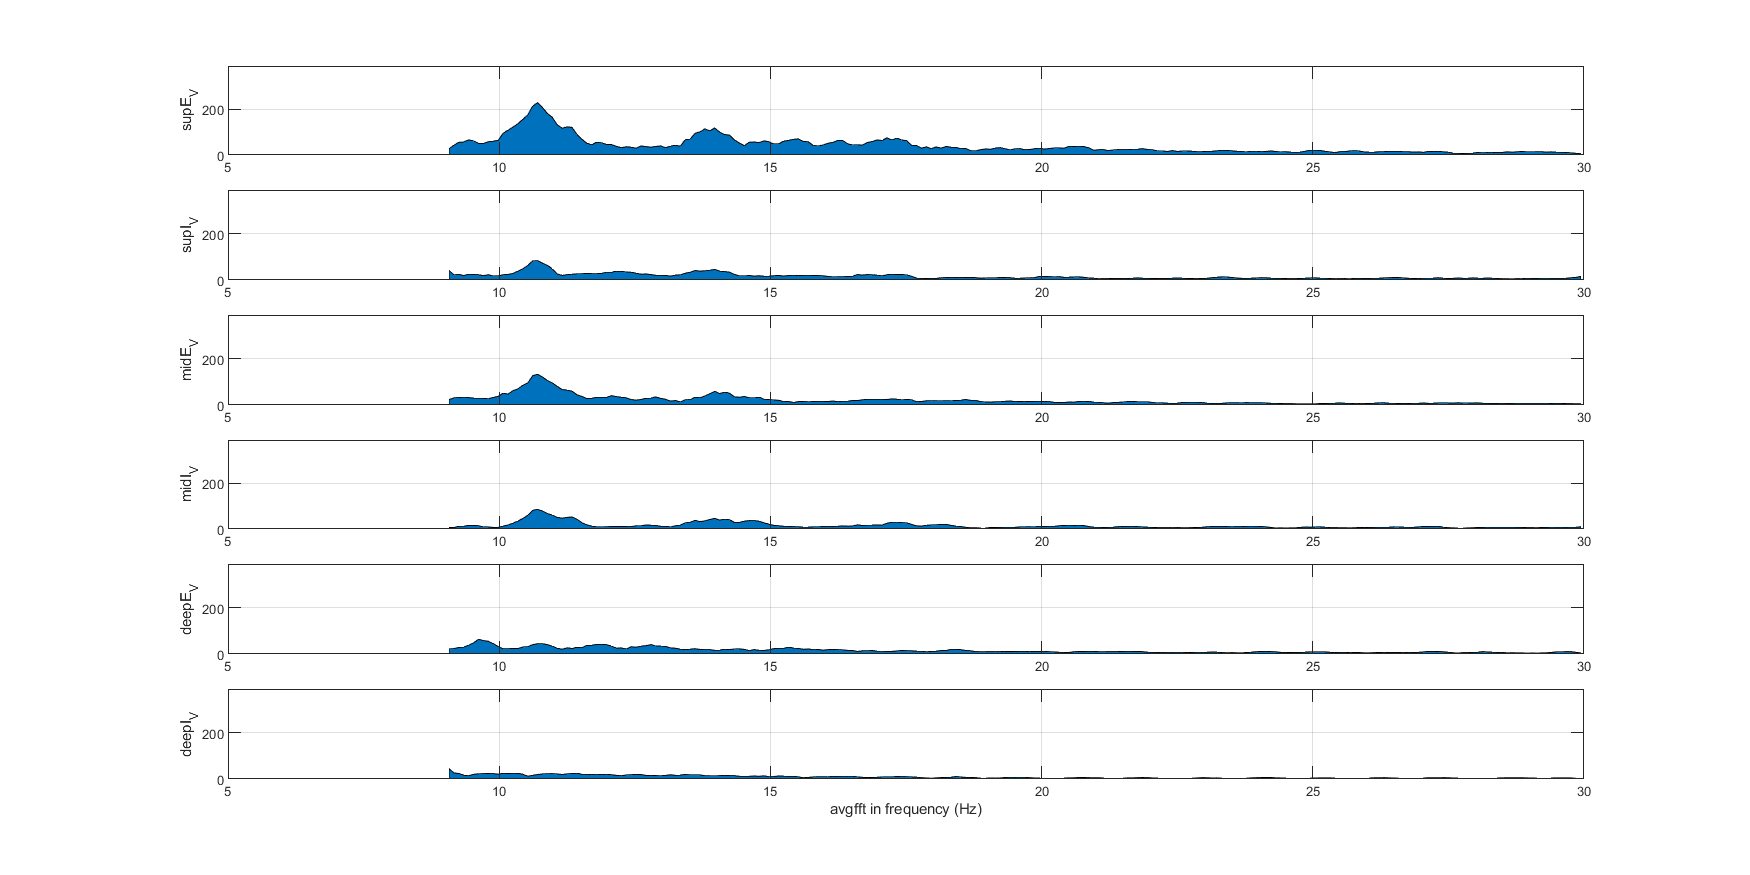

Temp edit for 6 subplots; average fft


opts("lf") = 9;
opts("hf") = 32;
m.dlPlotAllPotentials('avgfft', opts);

# *End*